# Vlasov Maxwell Solver

This code solves Vlasov-Maxwell/Poisson equation

$\frac{\partial f}{\partial t}+\mathrm{v}\nabla_x f+\mathbf{F}\cdot \nabla_v f=0$, 

where $\mathbf{F}=\mathbf{E}+\mathbf{v}\times \mathbf{B}$ (Maxwell Equation) or $\mathbf{F}=\nabla \phi$(Poisson Equation)

- Maxwell Equation: $\frac{\partial{\bf E}}{\partial t}=\nabla_{\bf x}\times{\bf B}-{\bf J}$, $\frac{\partial{\bf B}}{\partial t}=-\nabla_{\bf x}\times{\bf E}$, $\nabla_{\bf x}\cdot{\bf E}=\rho-\rho_i, \ \nabla_{\bf x}\cdot{\bf B}=0$ with $\rho({\bf x},t)=\int_{\Omega_{\bf v}}f({\bf x},{\bf v},t)d{\bf v}, \ {\bf J}({\bf x},t)=\int_{\Omega_{\bf v}}f({\bf x},{\bf v},t){\bf v}d{\bf v}$;

- Poisson Equation: $-\Delta\phi=\rho$, with $\rho({\bf x},t)=\int_{\Omega_{\bf v}}f({\bf x},{\bf v},t)d{\bf v}$.

The method has been used here is the discontinuous Galerkin sparse grids methods.

Ref: 

- Z. Wang, Q. Tang, W. Guo, Y. Cheng.[ Sparse Grid Discontinuous Galerkin Methods for High-dimensional Elliptic Equations](https://www.sciencedirect.com/science/article/pii/S002199911600156X). *Journal of Computational Physics*, 314 (2016): 244-263.

- W. Guo, Y. Cheng. [A Sparse Grid Discontinuous Galerkin Method for High-Dimensional Transport Equations and Its Application to Kinetic Simulations](https://epubs.siam.org/doi/abs/10.1137/16M1060017). *SIAM J. Sci. Comput.*, 38(2016), A3381–A3409. 

- Z. Tao, W. Guo, Y. Cheng. [Sparse Grid Discontinuous Galerkin Methods for the Vlasov-Maxwell System. ](https://arxiv.org/abs/1805.10747)

- B. Alpert. [A class of bases in L 2 for the sparse representation of integral operators](https://math.nist.gov/~BAlpert/l2bases.pdf). *SIAM J. Math. Anal., *24(1):246–262, 1993.

# 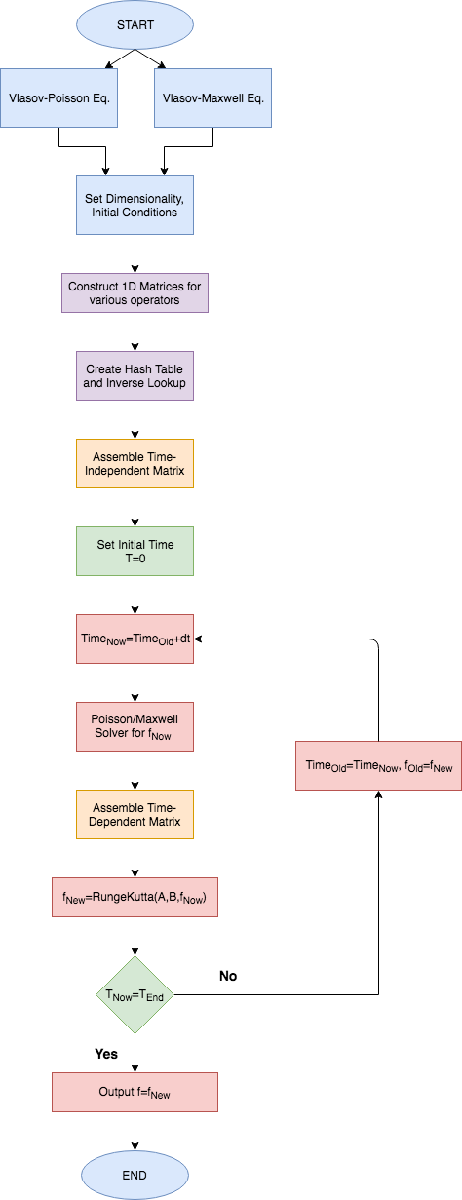

# Sparse Grids (Algorithm for HashTable)

% All combinations from choosing Dim numbers from vector [0:Lev]
combs = permn(0:Lev, Dim);

combs =      0     0     0
     0     0     1
     0     1     0
     0     1     1
     1     0     0
     1     0     1
     1     1     0
     1     1     1


% Find all Cells corresponding to the related Lev(1:Dim)
key = zeros(1,2*Dim);
count = 1;
for i = 1:size(combs,1)
    if sum(combs(i,:))<=Lev
        nLev = combs(i,:);
        nCell = AllCell(nLev);
        nz = size(nCell,1);
        for ii = 1:nz
            key(1:Dim) = nLev;
            key(Dim+1:end) = nCell(ii,:);
            forwardHash.(sprintf('i%g_',key))=count;
            
            index_dim = LevCell2index(nLev,nCell(ii,:));
               
            count=count+1;
        end
        
        
    end
end

forwardHash = struct with fields:
    i0_i0_i0_i0_i0_i0_: 1
    i0_i0_i1_i0_i0_i0_: 2
    i0_i1_i0_i0_i0_i0_: 3
    i1_i0_i0_i0_i0_i0_: 4


`For Example:`

`forwardHash = struct with fields:`

`    i0_i0_i0_i0_i0_i0_: 1`

`    i0_i0_i1_i0_i0_i0_: 2`

`    i0_i1_i0_i0_i0_i0_: 3`

`    i1_i0_i0_i0_i0_i0_: 4`